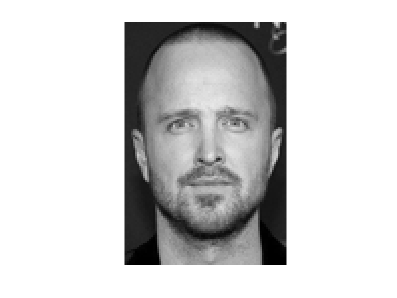

clc
clear
close all
m = 120;
n = 80;
n_images = 5;
images = zeros(m,n,n_images);
image1 = rgb2gray(imresize(imread('AaronPaul1.png'),[m,n]));
images(:,:,1) = image1;
imshow(image1);

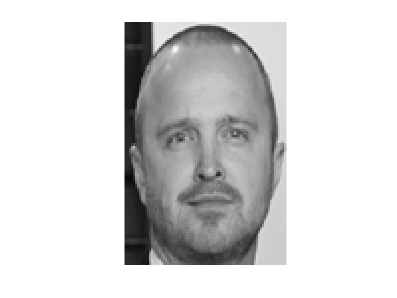

image2 = rgb2gray(imresize(imread('AaronPaul2.png'),[m,n]));
images(:,:,2) = image2;
imshow(image2);

image3 = rgb2gray(imresize(imread('AaronPaul3.png'),[m,n]));

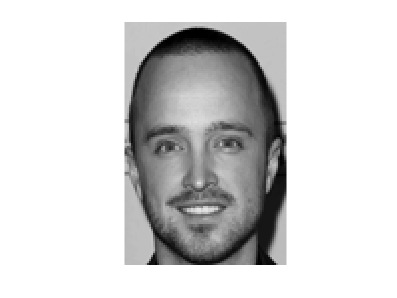

images(:,:,3) = image3;
imshow(image3);

image4 = rgb2gray(imresize(imread('AaronPaul4.png'),[m,n]));

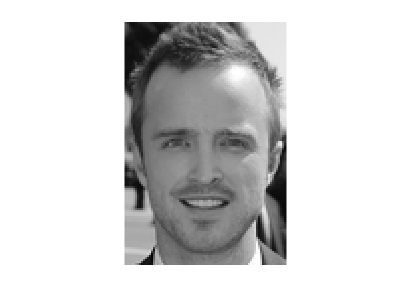

images(:,:,4) = image4;
imshow(image4);

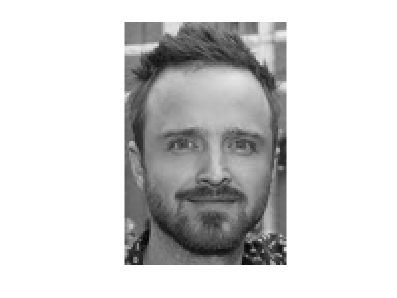

image5 = rgb2gray(imresize(imread('AaronPaul5.png'),[m,n]));
images(:,:,5) = image5;
imshow(image5);

## Prueba imagen normal

fam1 = matriz_a(n_images, m, n, images);
fam1

fam1 =     35    34    34    36    36    34    37    36    34    36    35    36    34    36    37    36    37    36    35    35    35    35    35    35    35    37    37    36    37    36    35    38    38    36    36    31    28    22    20    19    21    22    23    24    29    32    34    36    37    36
    39    37    34    31    27    25    24    28    36    40    42    40    38   122   207   226   228   227   227   228   227   227   226   226   226   225   226   224   224   226   225   224   224   224   227   231   233   236   237   236   234   235   234   231   230   227   226   226   223   223
   196   196   196   196   197   198   198   197   197   198   196   198   198   197   198   198   198   196   197   196   197   196   196   196   196   196   196   196   196   197   198   199   199   197   196   197   197   196   196   196   196   197   197   197   196   197   197   196   196   196
    71    46    22    18    18    21    32    37    40    45    47    48    39    30    23

## Cálculo de la matriz transpuesta

A1 = transpose(fam1)

A1 =     35    39   196    71   125
    34    37   196    46   124
    34    34   196    22   124
    36    31   196    18   128
    36    27   197    18   127
    34    25   198    21   126
    37    24   198    32   125
    36    28   197    37   131
    34    36   197    40   122
    36    40   198    45   114


## Cálcular C ( A.t * A)

C1 = A1 * fam1

C1 =        61828       59815       57994       58163       58078       58214       58936       59966       59296       59073       59866       61286       60749       63260       66434       67265       67625       66872       69729       74109       77587       79047       80195       81990       82220       81805       81310       82776       81717       76257       76606       73908       73763       74577       76046       76788       76466       74240       74214       72413       73138       75226       76892       78747       76048       72889       72591       73016       73323       71629
       59815       58433       57218       57487       57411       57479       57926       58818       58068       57718       58450       59840       59532       62098       65275       66068       66250       65429       68241       72656       76085       77263       77866       79158       79264       78877       78482       79354       78034       72470       72527       70096       698

## EigenValues

[V1,D1] = eigs(C1,20)

V1 =     0.0073    0.0154    0.0186   -0.0021   -0.0070   -0.0086   -0.0049   -0.0119    0.0054   -0.0057   -0.0031   -0.0112    0.0025    0.0036    0.0012    0.0021   -0.0048   -0.0087   -0.0058   -0.0030
    0.0068    0.0151    0.0205    0.0020   -0.0086   -0.0098    0.0006    0.0108    0.0006   -0.0124   -0.0042    0.0008    0.0067    0.0038   -0.0054   -0.0039   -0.0051   -0.0043    0.0020   -0.0042
    0.0064    0.0148    0.0226    0.0058   -0.0105   -0.0037   -0.0030   -0.0021   -0.0018    0.0003   -0.0047   -0.0074    0.0126   -0.0053   -0.0037   -0.0005    0.0024   -0.0013   -0.0044   -0.0060
    0.0064    0.0145    0.0233    0.0061   -0.0120    0.0255    0.0004    0.0093   -0.0078   -0.0006    0.0030   -0.0049   -0.0052    0.0004   -0.0059    0.0034    0.0021   -0.0031   -0.0056   -0.0081
    0.0063    0.0146    0.0239    0.0056   -0.0120   -0.0066    0.0014   -0.0031   -0.0041   -0.0029    0.0030    0.0040   -0.0046   -0.0036   -0.0009   -0.0006   -0.0132   -0.0050   -0.0039 

D1 = 1.0e+08 *

    8.1659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.3972         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.2471         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.1969         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.1190         0         0         0         0         0         0         0         0         0         0         0         0         0

## Reconstrucción de las imágenes del EigenVector

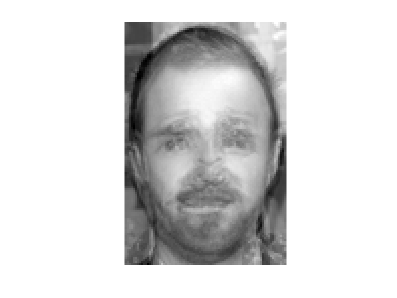

mat1 = zeros(m,n,20);
for i = 1:20
    image = transpose(reshape(V1(:,i),[n,m]));
    mat1(:,:,i) = image;
end

imshow(mat1(:,:,1),[])

## Imágen de prueba

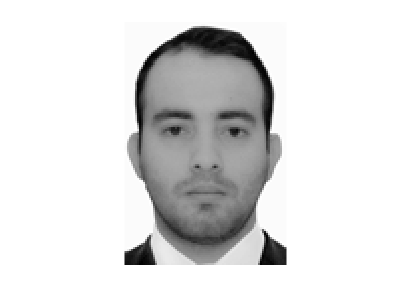

test_img = double(rgb2gray(imresize(imread('william.png'),[m,n])));
imshow(test_img,[])

test_v = reshape(transpose(test_img),[1,m*n]);

p = test_v * V1;

X = V1 * transpose(p);

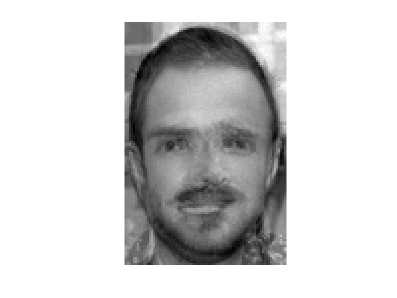

image_r = transpose(reshape(X,[n,m]));
imshow(image_r,[])

## Calcular el error

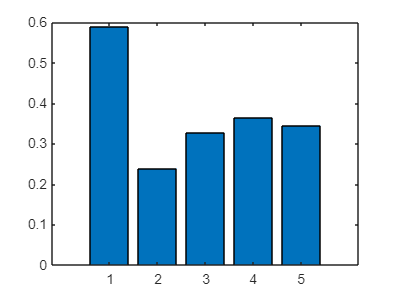

errors = calcular_error(fam1, V1, test_v);
bar(errors)

mean(errors)

ans = 0.3723

## Imágen de prueba equalización

fam1 = matriz_a_eq(n_images, m, n, images);

A1 = transpose(fam1);

C1 = A1 * fam1;

[V1,D1] = eigs(C1,20);

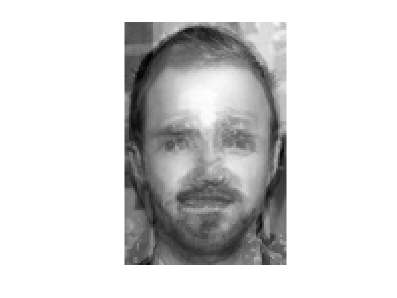

mat1 = zeros(m,n,20);
for i = 1:20
    image = transpose(reshape(V1(:,i),[n,m]));
    mat1(:,:,i) = image;
end

imshow(mat1(:,:,1),[])

test_img = rgb2gray(imresize(imread('william.png'),[m,n]));
imshow(test_img,[])

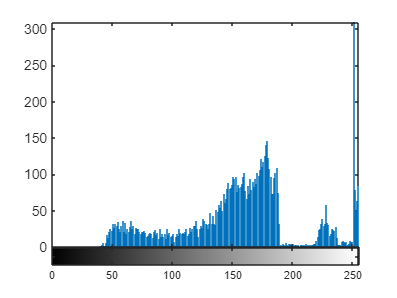

[counts,binLocations] = imhist(test_img);
imhist(test_img);

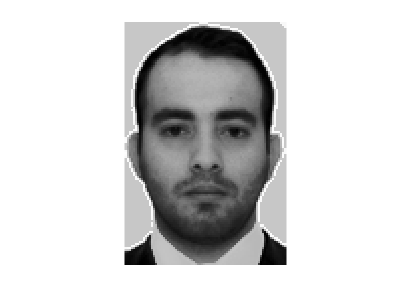

[s,image_t] = equalization(test_img,counts);

imshow(image_t)

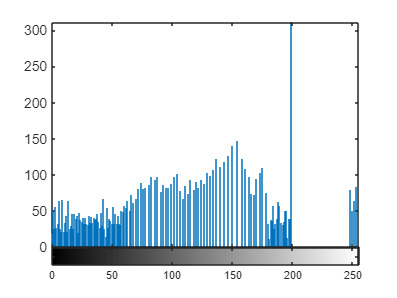

imhist(image_t)

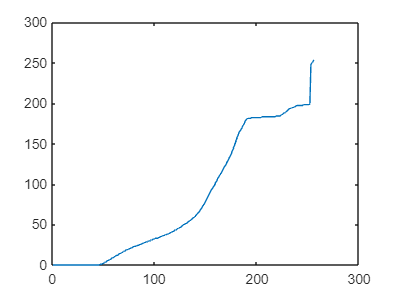

counts_s = imhist(image_t);
plot(s)

test_v = reshape(transpose(double(image_t)),[1,m*n]);

p = test_v * V1;

X = V1 * transpose(p);

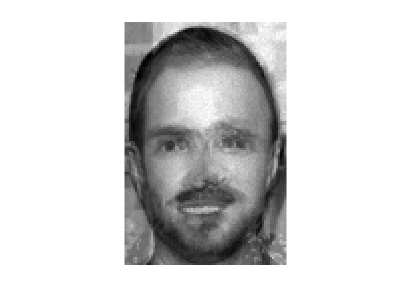

image_r = transpose(reshape(X,[n,m]));
imshow(image_r,[])

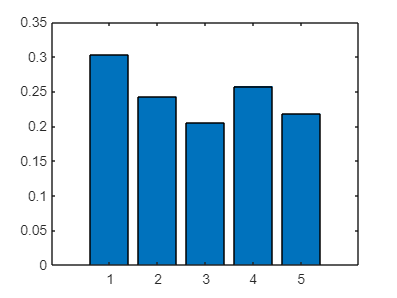

errors1 = calcular_error(fam1, V1, test_v);
bar(errors1)

mean(errors1)

ans = 0.2453